clc; clear;

vrep = remApi('remoteApi');

Note: always make sure you use the corresponding remoteApi library
(i.e. 32bit Matlab will not work with 64bit remoteApi, and vice-versa)


vrep.simxFinish(-1);
id = vrep.simxStart('127.0.0.1', 19000, true, true, 5000, 5);

## Get Handles

%https://manual.coppeliarobotics.com/en/remoteApiFunctionsMatlab.htm
[err, camhandle] = vrep.simxGetObjectHandle(id,'./VelodyneVPL16', vrep.simx_opmode_oneshot_wait);

## Get Image

tic;
full_vect = zeros(1,1);
[returnCode, SignalValue] = vrep.simxReadStringStream(id,'datos', vrep.simx_opmode_streaming);
for n = linspace(1, 4, 4)
    [returnCode, SignalValue] = vrep.simxReadStringStream(id,'datos', vrep.simx_opmode_buffer);
    RealValue = vrep.simxUnpackFloats(SignalValue);
    full_vect = cat(2, full_vect, RealValue);
    pause(0.1)
end
full_vect = full_vect(2:end);
toc;

Elapsed time is 0.433160 seconds.


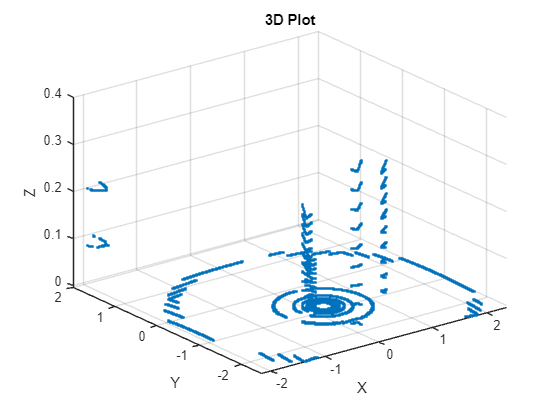

M = length(full_vect) / 3;
B = reshape(full_vect, [3, M]);
x = B(1, :); y = B(2, :); z = B(3, :);
figure; plot3(x, y, z, '.', "LineWidth", 0.5); xlabel('X');
ylabel('Y'); zlabel('Z'); title('3D Plot');
grid on;

LOL

## Move Pioneer

[err, left_Motor] = vrep.simxGetObjectHandle(id,'./leftMotor',vrep.simx_opmode_blocking);
[err, right_Motor] = vrep.simxGetObjectHandle(id,'./rightMotor',vrep.simx_opmode_blocking);

[err] = vrep.simxSetJointTargetVelocity(id,left_Motor,0.1,vrep.simx_opmode_blocking);
[err] = vrep.simxSetJointTargetVelocity(id,right_Motor,0.1,vrep.simx_opmode_blocking);
